# Center of Buoyancy

This notebook is about computing the center of mass and center of buoyancy for a cross section of a boat (or other object) in 2D.  It introduces some of the MATLAB tools you will need for the boat project, and a framework for doing this kind of computation.

As you work through the notebook, take time to understand the code.

- Make changes to see what effect they have.  

- Make errors and see what happens.  

- For the MATLAB functions we use, read the documentation.

- For the functions defined at the end of the notebook, read the code!

- For each exercise, make an initial effort to do it on your own.

If you get stuck, make a reasonable effort to get unstuck -- you can learn a lot that way -- but don't stay stuck too long.  Ask for help from another student, a NINJA, or an instructor.

Then, once you get unstuck, take a minute to be sure you really understand the answer.

Remember that the goal is not just to finish the exercise and be done.  The goal is to learn what you need to know to work effectively on the project (and future projects).

Have fun!

clear all

## Defining the boat

We'll start with a hypothetical boat that's 30 cm long, 20 cm wide, and 10 cm deep.  Again, we'll use a MATLAB structure to contain information about the boat.

We'll express all quantities in this notebook using SI units, mostly meters and kilograms.

boat.L = 0.30;         % length in meters
boat.W = 0.20;         % width in meters
boat.HB = boat.W / 2;  % half breadth in meters
boat.D = 0.10;         % depth in meters

boat.mass = 1.5;       % kg
boat.n = 2;            % shape parameter (dimensionless)

Just so we get calibrated, let's compute the area, volume, and mass of a rectangular solid with these dimensions, filled with water.

max_area = boat.D * boat.W

max_area = 0.0200

max_volume = max_area * boat.L 

max_volume = 0.0060

density_water = 1025;    % kg / m^3
max_mass = max_volume * density_water

max_mass = 6.1500

Next we'll define a 2D mesh, similar to what we saw in the previous notebook.

Here's the coordinate system we'll use.

- x is the direction along the length of the boat

- y is along the width of the boat

- z is along the height/depth of the boat

dy = 0.01;   % meters
dz = 0.01;   % meters

mesh.ys = -boat.HB:dy:boat.HB;        % meters
mesh.zs = 0:dz:boat.D;                % meters

[mesh.ygrid,mesh.zgrid] = meshgrid(mesh.ys,mesh.zs);
mesh

mesh = struct with fields:
       ys: [-0.1000 -0.0900 -0.0800 -0.0700 -0.0600 -0.0500 -0.0400 -0.0300 -0.0200 -0.0100 0 0.0100 0.0200 0.0300 0.0400 0.0500 0.0600 0.0700 0.0800 0.0900 0.1000]
       zs: [0 0.0100 0.0200 0.0300 0.0400 0.0500 0.0600 0.0700 0.0800 0.0900 0.1000]
    ygrid: [11×21 double]
    zgrid: [11×21 double]


dA is the area of one cell in the mesh, in square meters.

total_area = boat.W * boat.D       % m^2

total_area = 0.0200

mesh.dA = total_area / numel(mesh.ygrid)

mesh = struct with fields:
       ys: [-0.1000 -0.0900 -0.0800 -0.0700 -0.0600 -0.0500 -0.0400 -0.0300 -0.0200 -0.0100 0 0.0100 0.0200 0.0300 0.0400 0.0500 0.0600 0.0700 0.0800 0.0900 0.1000]
       zs: [0 0.0100 0.0200 0.0300 0.0400 0.0500 0.0600 0.0700 0.0800 0.0900 0.1000]
    ygrid: [11×21 double]
    zgrid: [11×21 double]
       dA: 8.6580e-05


We'll use a power function to describe the shape of the hull.


$$z = D |y/HB|^n$$


where D is the depth of the boat and HB is the half breadth.

y = mesh.ys;
n = boat.n;
z = boat.D * abs(y/boat.HB).^n

z =     0.1000    0.0810    0.0640    0.0490    0.0360    0.0250    0.0160    0.0090    0.0040    0.0010         0    0.0010    0.0040    0.0090    0.0160    0.0250    0.0360    0.0490    0.0640    0.0810    0.1000


plot(y, z)

Next we will use a* logical matrix* to represent the cells that are inside and outside the boat.  A logical matrix (also called a boolean matrix) contains only the values 0 and 1, where 0 represents "false" and 1 represents "true".

You create a logical matrix by applying comparison operations to numerical matrixes.  In the following example, **hull** has the same shape as **mesh.zgrid**; it contains 1 (true) wherever the **z** coordinate in the mesh exceeds the function we just computed, and 0 (false) otherwise.

hull = mesh.zgrid > z

hull = 11×21 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   1   1   1   1   1   1   1   0   0   0   0   0   0   0
   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0
   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0
   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0
   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0
   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0
   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0
   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0


If you look at the values in **hull**, they will seem upside-down.  That's a side effect of the way we defined the mesh.

We can visualize the hull using **image**, which is a MATLAB function that treats a matrix as an image.  **redmap** is a colormap that uses red to represent 1 and white to represent 0.

**flipud** is a MATLAB function that flips a matrix upside-down.

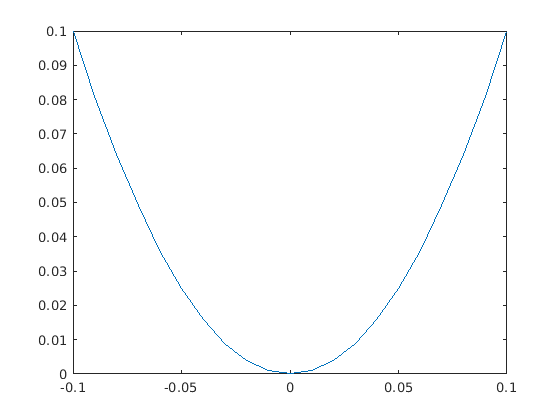

redmap = [1,1,1;1,0,0];
colormap(redmap);

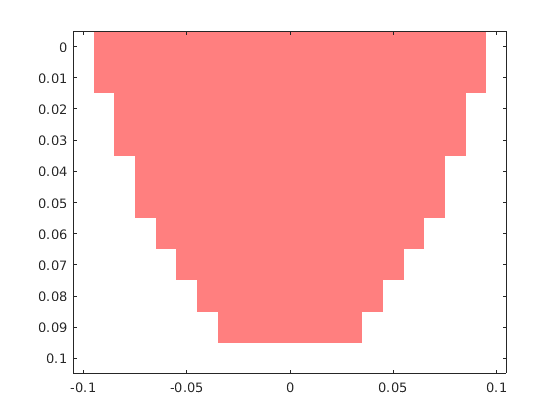

image(mesh.ys,mesh.zs,flipud(hull),'AlphaData',0.5);

**Exercise 1:** Use the code from the previous section to fill in the body of **computeHull** and **plotMatrix** , below, and then test them using the following lines of code.

Note: If you run this code now, it will run, but it won't do the right thing until you fix **computeHull**.

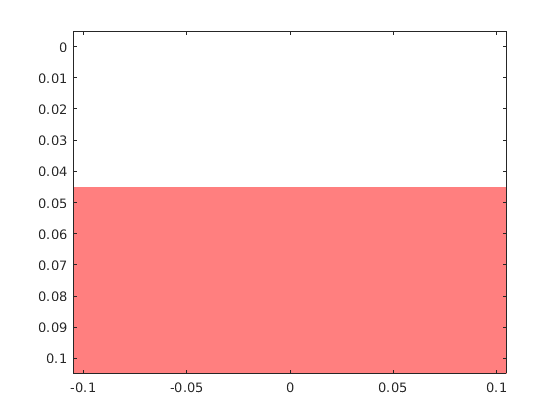

boat.hull = computeHull(mesh,boat);
plotMatrix(boat.hull,mesh,redmap);

**Exercise 2:** 

- Use **matrixSum** (which we saw in the previous notebook) to compute the total number of cells in this hull section.  

- Compute the area of the section in square meters.  Does it seem about right compared to **max_area**?

- Assuming that the section of the boat is the same from bow to stern, compute the total volume of the hull.  Does it seem about right compared to **max_volume**?

- Compute the total mass of water the boat would displace if fully submerged.  Does it seem about right compared to **max_mass**?

What happens to the shape of the hull as we increase the shape parameter, **n**?

boat.num_cells = matrixSum(boat.hull);

## Center of mass

To compute center of mass, let's use **boat.hull** to compute a matrix of masses.

Multiplying a logical matrix by a scalar yields a numerical matrix.

boat.mass_per_cell = boat.mass / boat.num_cells;
masses = hull * boat.mass_per_cell;

**Exercise 3:**

- Use **matrixSum** to compute the total mass of **masses**, and confirm that it matches the total mass of the boat, **boat.mass**.

- Fill in the body of **centerOfMass2**, below, so it computes the center of mass in the y-z plane.

- Compute the center of mass for the hull.  What do you expect the y coordinate to be?  Does the z coordinate seem about right?

- What happens to the center of mass as we increase the shape parameter, **n**?

**Exercise 4:** Add 0.5 kg of ballast at the bottom of the boat and recompute the center of mass.  Does the COM shift in the way you expect?

Hint: make a copy of **addMass2** from the previous notebook and modify it to work in the y-z plane.

## Representing the water

In the same way we built a logical matrix to represent the hull, we'll create another to represent the water.

We'll parameterize the waterline using **theta** to indicate the angle of the water relative to the deck of the boat, and **d** to represent the height of the water, also relative to the deck.

Here's an example:

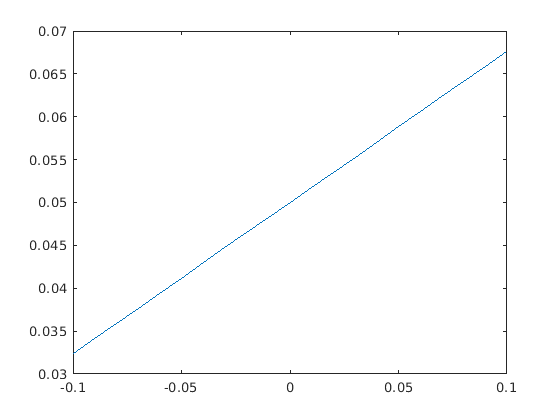

d = 0.05;
theta = 10;

y = mesh.ys;
z = tand(theta) .* y + d;

plot(y,z)

Now we'll compute a logical matrix that's 1 where there's water and 0 elsewhere.

water = mesh.zgrid < z;

And here's what it looks like.

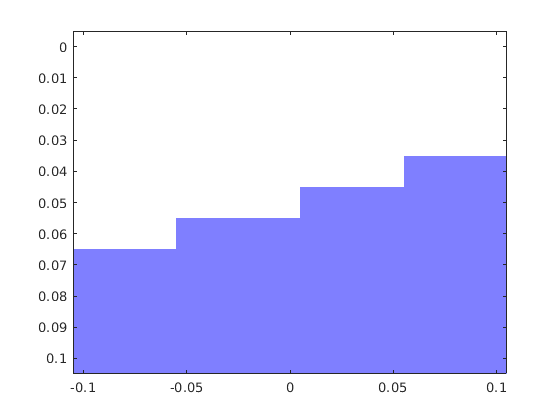

bluemap = [1,1,1; 0,0,1];
plotMatrix(water,mesh,bluemap);

You might wonder why we are rotating the water rather than rotating the boat.  The short answer is that it was easier to write the program this way.  There are definitely pros and cons to this decision.  In your code for the project, you might consider rotating the boat instead, and see if you think it's a better design.

**Exercise 5:** Use the code from the previous section to fill in the body of **computeWater**, below, and test it below using the following code.

Note: If you run this code now, it will run, but it won't do the right thing until you fix **computeWater**.

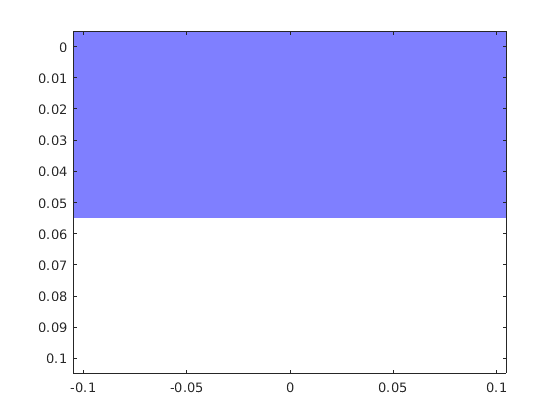

water = computeWater(d,theta,mesh);
plotMatrix(water,mesh,bluemap);

## Computing the submerged region

At this point we have a logical matrix that represents the hull and another logical matrix that represents the water.  We can use logical operators to compute the union and intersection of logical matrices.

If A and B are logical matrices

- **A&B** finds the intersection; that is, the cells that are in both regions, "A and B".

- **A|B** finds the union; that is, cells that are in either region, "A or B"

So we can compute the submerged region like this

sub_region = boat.hull & water;

And plot it like this

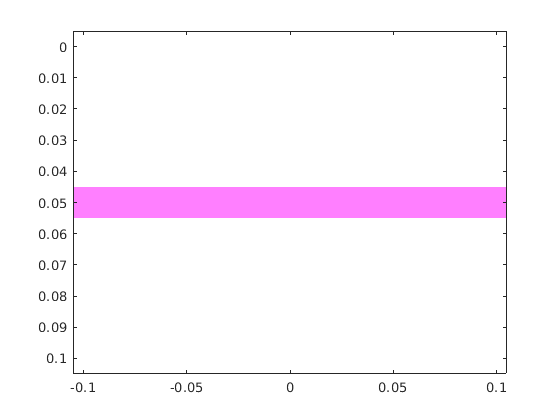

purplemap = [1,1,1; 1,0,1];
plotMatrix(sub_region,mesh,purplemap);

## Center of buoyancy

The center of buoyancy is the center of mass of the displaced water.  The density of well mixed water is very close to constant, so we can compute the center of buoyancy by computing the center of mass of **sub_region**.

COB = centerOfMass2(sub_region,mesh)

COB =     0.0000    0.0500


**Exercise 6:** Test this code with a range of values for theta and d.  Does the COB seem to be in the right place?

What happens when theta exceeds 90 degrees?  Can you fix **computeWater** so it handles this case correctly?

## Function definitions

function hull = computeHull(mesh,boat)
    % computeHull: compute the shape of the hull
    % mesh: structure that contains y
    % boat: structure that contains n
    % returns: logical matrix
    
    % TODO: fill this in
    hull = mesh.zgrid < 0.06;
end

function plotMatrix(A,mesh,cmap)
    % plotMatrix: plots a matrix using image
    % A: matrix
    % mesh: srtruct containing ys and zs
    % cmap: Colormap
    colormap(cmap);
    image(mesh.ys,mesh.zs,flipud(A),'AlphaData',0.5);
end

function M = matrixSum(A)
    % matrixSum: returns total of all elements in the matrix
    % A: matrix
    % returns: scalar
    
    % normally sum(m) computes the sums of the columns
    % selecting m(:) flattens the matrix and computes the sum of all elements
    % see https://stackoverflow.com/questions/1721987/what-are-the-ways-to-sum-matrix-elements-in-matlab
    M = sum(A(:));
end

function COM = centerOfMass2(masses,mesh)
    % centerOfMass2: computes center of mass in 2D
    % masses: matrix of masses
    % mesh: structure containing ygrid and zgrid
    % returns: Vector [ycom,zcom]
    M = matrixSum(masses);
    ycom = matrixSum(masses .* mesh.ygrid) / M;
    zcom = matrixSum(masses .* mesh.zgrid) / M;
    COM = [ycom,zcom];
end

function masses = addMass2(mass,position,masses,mesh) 
    % addMass2: adds mass at a given position in 2D
    % mass: scalar, in grams
    % position: scalar, in cm
    % masses: matrix of masses
    % mesh: structure containing ys and zs
    % returns: the updated matrix of masses
    
    % TODO: fill this in
    masses = masses;
end

function index = closestIndex(coord,grid)
    % closestIndex: finds the index of the grid point closest to coord
    % coord: scalar coordinate
    % grid: matrix of coordinates
    % returns: integer index
    
    % see: https://www.mathworks.com/matlabcentral/answers/152301-find-closest-value-in-array
    [c index] = min(abs(coord-grid));
end

function water = computeWater(d,theta,mesh)
    % water: compute the level of the water
    % d: depth of waterline in meters
    % theta: angle of waterline in degrees
    % mesh: structure containing ys and zgrid
    % returns: logical matrix
    
    % TODO: fill this in
    water = mesh.zgrid > 0.04;
end






